# Project “Vessel Detection in Endoscopic Data”

clc;
close all;
clear;

## Load image

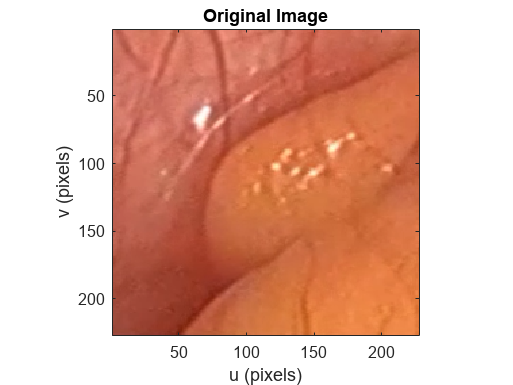

path = fullfile("images_endovideo","random","frame_left32819.png");
img = iread(path, 'uint8');
figure;
idisp(img, 'here', 'square');
title('Original Image');

## Smoothing with Gauss or Laplace and Padding

- Das Bild wird mit einem Gauss- oder Laplace-Filter geglättet.

- Das Bild wird normalisiert und in Gleitkommazahlen konvertiert.

- Es wird ein Padding hinzugefügt, um Randartefakte zu vermeiden.

- Die Glättungsoperation wird auf das gepaddete Bild angewendet.

- Das Ergebnis wird beschnitten, um die gepaddeten Bereiche zu entfernen.

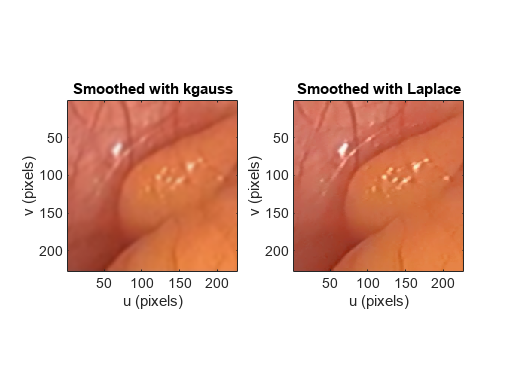

gauss = kgauss(2);
img_normalized = double(img) / double(max(img(:)));

% Padding hinzufügen
padding = [5,5];
padded_img = padarray(img_normalized, padding, 'replicate', 'both');
imConv = iconvolve(padded_img, gauss, 'same');
imConv = imConv(padding(1)+1:size(img,1)+padding(1), padding(1)+1:size(img,2)+padding(1), :);
smooth_img = locallapfilt(single(padded_img), 0.1, 2);
smooth_img = smooth_img(padding(1)+1:size(img,1)+padding(1), padding(1)+1:size(img,2)+padding(1), :);


figure;
subplot(121);
idisp(imConv, 'here', 'square');
title('Smoothed with kgauss');
subplot(122);
idisp(smooth_img, 'here', 'square');
title('Smoothed with Laplace')

## **Edge Enhancement with Gaus-Filter und Padding**

- Das geglättete Bild wird zur Kantenverstärkung verwendet.

- Das Bild wird erneut gepaddet, um Randartefakte zu vermeiden.

- Das Bild wird mit einem Derivat des Gauss-Filters (DoG) gefaltet, um die Gradienten zu berechnen.

- Die Magnitude der Gradienten wird berechnet.

- Die Kantenkarte wird normalisiert.

- Das verstärkte Bild wird erhalten, indem die Kantenkarte mit dem geglätteten Bild mit einer bestimmten Stärke addiert wird.

- Die Pixelwerte werden auf den Bereich [0, 1] begrenzt.

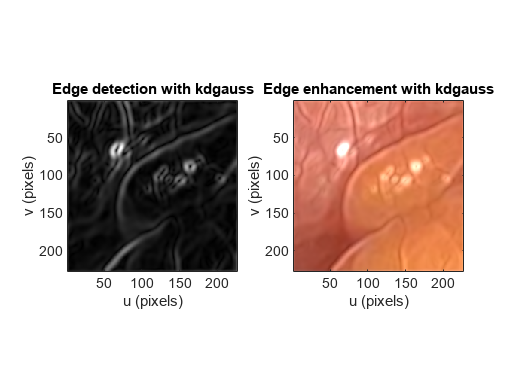

smooth_img = imConv; % gauss filter for smoothing
% smooth_img = img; % no smoothing
smooth_img_padded = padarray(smooth_img, padding, 'replicate');
G = kdgauss(3)./3^2;
[Igu, Igv] = isobel(smooth_img_padded, G);
% magnitude
Imag = sqrt(Igu.^2 + Igv.^2);
% Normalize the edges
Imag = Imag ./ max(Imag(:));
Imag = Imag(padding(1)+1:size(img,1)+padding(1), padding(1)+1:size(img,2)+padding(1));
% Reinforce the edges
edge_strength = 1.0; % Anpassen des Verstärkungsfaktors
enhanced_img = im2double(smooth_img) + edge_strength * Imag;
% Limit the value range to [0, 1].
enhanced_img = max(min(enhanced_img, 1), 0);

figure;
subplot(121);
idisp(Imag, 'here', 'square');
title('Edge detection with kdgauss');
subplot(122);
idisp(enhanced_img, 'here');
title('Edge enhancement with kdgauss');

## Increasing Contrasts in Image

- Das verstärkte Bild wird in den LAB-Farbraum konvertiert.

- Der maximale Helligkeitswert wird definiert.

- Der L-Kanal (Helligkeit) des LAB-Bildes wird normalisiert und histogrammausgeglichen.

- Das LAB-Bild wird zurück in den RGB-Farbraum konvertiert.

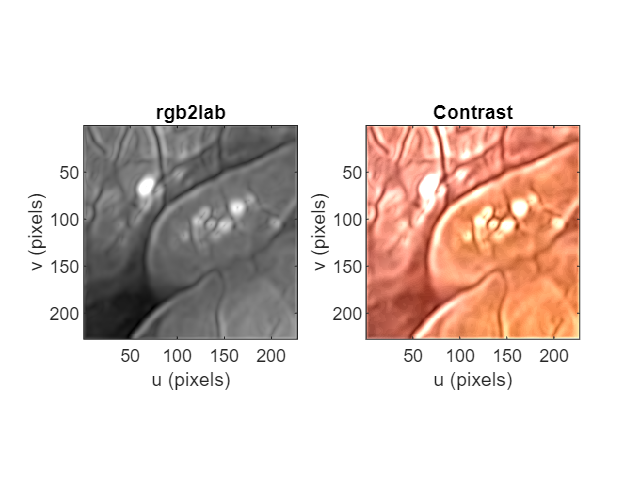

shadow_lab = rgb2lab(enhanced_img);
max_luminosity = 200;
L = shadow_lab(:,:,1)/max_luminosity;

shadow_img = shadow_lab;
shadow_img(:,:,1) = adapthisteq(L)*max_luminosity;
shadow_img = lab2rgb(shadow_img);

figure;
subplot(121);
idisp(L, 'here', 'square');
title('rgb2lab')
subplot(122);
idisp(shadow_img, 'here', 'square');
title('Contrast')

## Erosion and Dilatation

- Ein Strukturelement (kreisförmig) für morphologische Operationen wird definiert.

- Das erodierte Bild wird durch Anwendung der Erosionsoperation auf das kontrastverstärkte Bild erhalten.

- Das dilatierte Bild wird durch Anwendung der Dilatationsoperation auf das erodierte Bild erhalten.

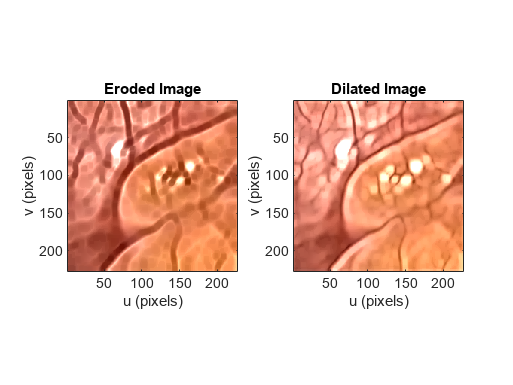

se = strel('disk', 3);
img_eroded = imerode(shadow_img, se);
img_dilated = imdilate(img_eroded, se);

figure;
subplot(121)
idisp(img_eroded, 'here', 'square');
title('Eroded Image');
subplot(122)
idisp(img_dilated, 'here', 'square');
title('Dilated Image');

## Segmentation

### Segmentation with kmeans

- Das erodierte und dilatierte Bild wird in den uint8-Format konvertiert. 

- Die Anzahl der Farben (Cluster) für die Segmentierung wird definiert. 

- K-Means-Clustering wird angewendet, um das Bild in verschiedene Regionen zu segmentieren. 

- Das gelabelte Bild wird über das Originalbild gelegt, um es zu visualisieren.

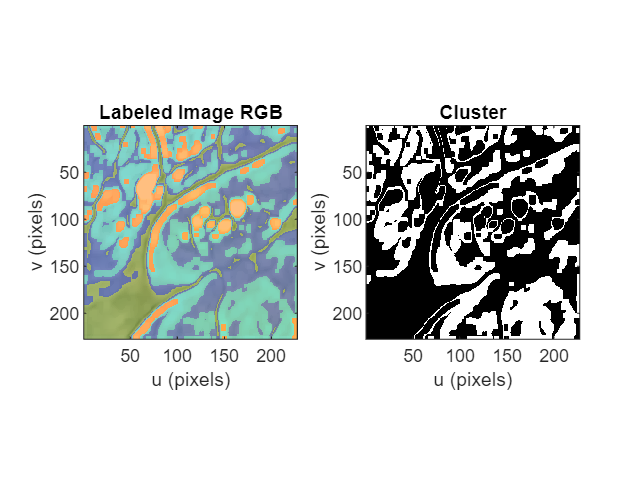

% Segmentation --> Segment Image via Kmeans
sharpened_img_int = im2uint8(img_dilated);
numColors = 4;
L = imsegkmeans(sharpened_img_int, numColors);
B = labeloverlay(sharpened_img_int, L);

lab_img = rgb2lab(B);
ab = lab_img(:,:,2:3);
ab = im2single(ab);
pixel_labels = imsegkmeans(ab,numColors,NumAttempts=3);
mask_kmeans = pixel_labels == 3;

figure;
subplot(121);
idisp(B, 'here', 'square');
title("Labeled Image RGB");
subplot(122);
idisp(mask_kmeans, 'here', 'square');
title("Cluster");

## Segmentation with chromatically coordination calculation

- Das endgültige Bild (dilatiert) wird zur Segmentierung anhand der chromatischen Koordinaten verwendet. 

- Die Rot (r) und Grün (g) Kanäle werden extrahiert. 

- Histogramme der r- und g-Kanäle werden berechnet. 

- Schwellenwerte werden basierend auf den Histogrammen bestimmt, um das Bild zu segmentieren. 

- Die segmentierten Bereiche werden kombiniert, um die endgültige Maske zu erhalten.

final_img = img_dilated;
% compute the chromaticity coordinates
[r,g] = tristim2cc(final_img);
histogram_r = histcounts(r, 'BinLimits', [0, 1], 'BinWidth', 0.01);
threshold_r = find(histogram_r >= 1000, 1, 'last') / 100; % 0.01 entspricht der Bin-Breite
[max_pixels_r, max_index_r] = max(histogram_r);
x_value_r = (max_index_r - 1) * 0.01; % 0.01 entspricht der Bin-Breite

histogram_g = histcounts(g, 'BinLimits', [0, 1], 'BinWidth', 0.01);
threshold_g = find(histogram_g >= 1000, 1, 'first') / 100; % 0.01 entspricht der Bin-Breite
[max_pixels_g, max_index_g] = max(histogram_g);
x_value_g = (max_index_g - 1) * 0.01; % 0.01 entspricht der Bin-Breite

% Breite des Bereichs mit den meisten Grauwerten
conncomp_r = regionprops(histogram_r >= 300, 'BoundingBox');
width_r = conncomp_r(1).BoundingBox(3)/100;
conncomp_g = regionprops(histogram_g >= 300, 'BoundingBox');
width_g = conncomp_g(1).BoundingBox(3)/100;

fprintf('Der größte Grauwert in r mit mindestens 1000 Pixeln: %.2f\n', threshold_r);

Der größte Grauwert in r mit mindestens 1000 Pixeln: 0.55


fprintf('Der kleinste Grauwert in g mit mindestens 1000 Pixeln: %.2f\n', threshold_g);

Der kleinste Grauwert in g mit mindestens 1000 Pixeln: 0.25


fprintf('Der x-Wert für r mit den meisten Pixeln: %.2f\n', x_value_r);

Der x-Wert für r mit den meisten Pixeln: 0.51


fprintf('Der x-Wert für g mit den meisten Pixeln: %.2f\n', x_value_g);

Der x-Wert für g mit den meisten Pixeln: 0.29


fprintf('Die Breite des Bereichs mit den meisten Grauwerten in r: %d\n', width_r);

Die Breite des Bereichs mit den meisten Grauwerten in r: 1.800000e-01


fprintf('Die Breite des Bereichs mit den meisten Grauwerten in g: %d\n', width_g);

Die Breite des Bereichs mit den meisten Grauwerten in g: 1.200000e-01


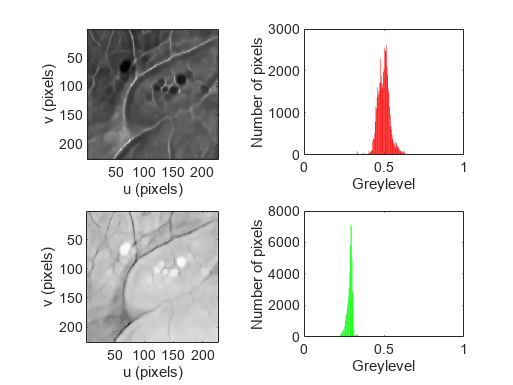



% display histogram of r and g coordinates
figure;
subplot(221); 
idisp(r, 'here', 'square'); 
subplot(222); 
ihist(r,'r'); ax=axis; axis([0 1 ax(3:4)]);

subplot(223); 
idisp(g, 'here', 'square'); 
subplot(224); 
ihist(g,'g'); ax=axis; axis([0 1 ax(3:4)]);

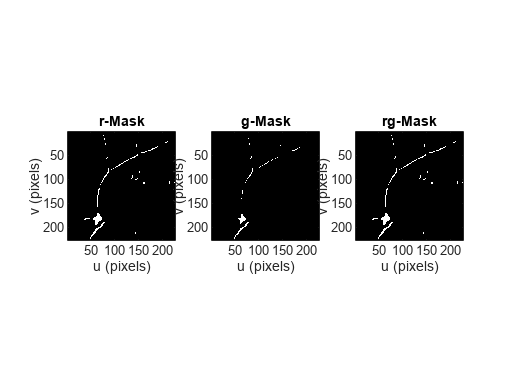


% define a mask image (true = pixel is part of object)
% mask = r > 0.64;
mask = r > x_value_r+(width_r/2);
maskr = icolor(idouble(mask));

%-----------------------------------------------------
% mask = g < 0.22;
mask = g < x_value_g-(width_g/2);
maskg = icolor(idouble(mask));

%-----------------------------------------------------
maskrg = maskr | maskg;
% maskrg = maskr & maskg;

figure;
subplot(131); 
idisp(maskr, 'here', 'square');
title('r-Mask');

subplot(132); 
idisp(maskg, 'here', 'square');
title('g-Mask');

subplot(133); 
idisp(maskrg, 'here', 'square');
title('rg-Mask');

## Segmentation with colorkmeans

- Das endgültige Bild (dilatiert) wird zur Segmentierung mit colorkmeans verwendet. 

- Das Bild wird in eine festgelegte Anzahl von Farben (Clustern) unterteilt. 

- Die segmentierten Bereiche werden anhand der angegebenen Farblabels extrahiert.

rng('default');  % Setzen Sie den Zufallszahlengenerator auf den Standardwert
[cls, cxy] = colorkmeans(final_img, 6);

 1:       0.477      0.4781      0.5211      0.4478      0.4205      0.3553 
 2:      0.3816      0.3555      0.3613      0.3614      0.3522      0.3481 


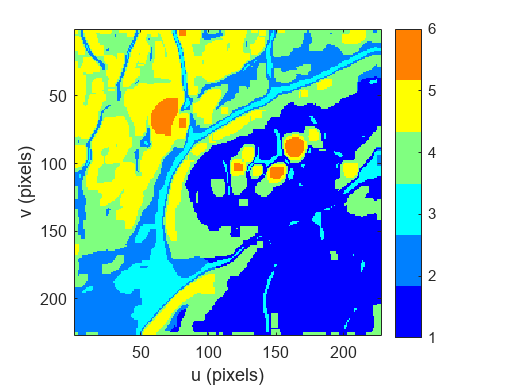

figure()
idisp(cls, 'here','colormap', 'Jet(6)', 'bar')

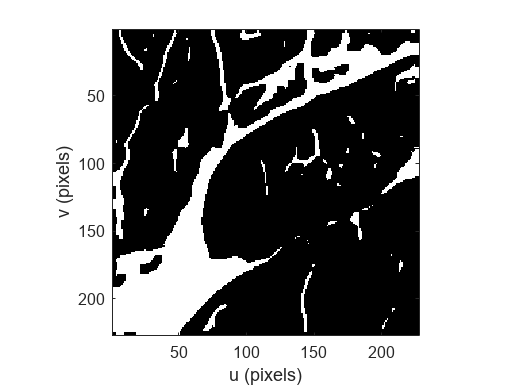


cls_i = (cls == 2 | cls == 3);
figure()
idisp(cls_i,'here', 'square')

## Morphology

- Die segmentierten Bereiche werden morphologischen Operationen unterzogen.

- Ein Strukturelement (kreisförmig) wird definiert.

- Die geschlossenen Regionen (binarisiert) werden erhalten, indem die segmentierten Bereiche geschlossen werden.

- Die geschlossenen Regionen werden skelettiert, um das Ergebnis der Blutgefäßdetektion zu erhalten.

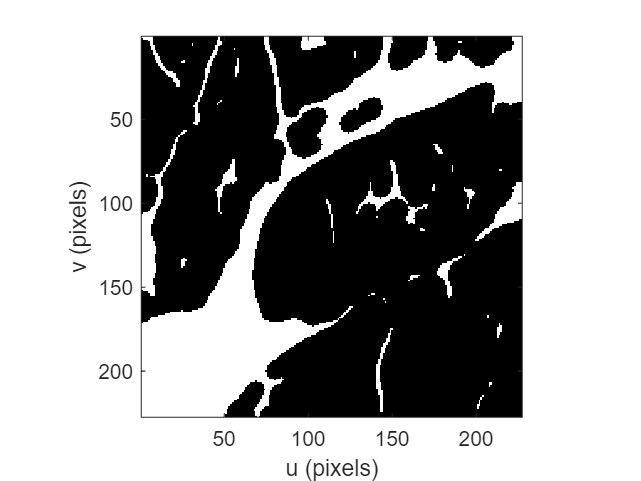

% cls_i = maskrg(:,:,1); % chromatically coordination calculation
% cls_i = mask_kmeans(:,:,1); % kmeans
% cls_i = cls_i; % colorkmeans

se = kcircle(5);
closed = imbinarize(iclose(cls_i, se, 1));
figure()
idisp(closed,'here', 'square')

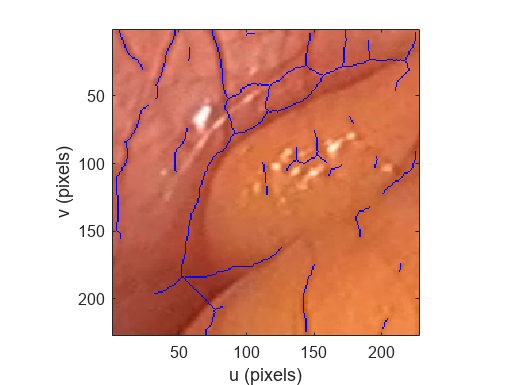

% clean = iopen(closed, se);
% figure()
% idisp(clean,'here', 'square')
out = bwskel(closed,'MinBranchLength',5);

figure()
idisp(labeloverlay(img, out, 'Transparency', 0),'here')

## Use of Function

 1:      0.4248      0.3148      0.3621      0.5159 
 2:      0.3562      0.3217      0.3409      0.3731 


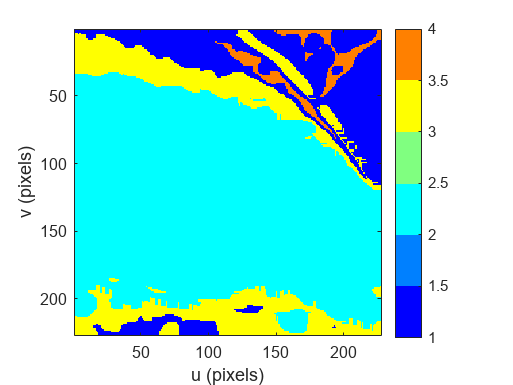

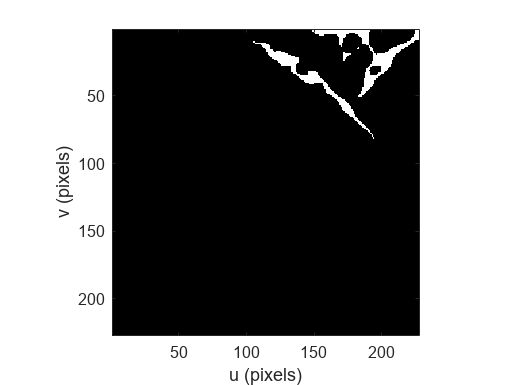

path = fullfile("images_endovideo","random","frame_left12561.png");
img1 = iread(path, 'uint8');
gauss = 2;
max_luminosity = 90;
num_Colors = 7;
cls_num = [0,4];
blood_vessel = blood_vessel_detection(img1, gauss, max_luminosity, numColors, cls_num);

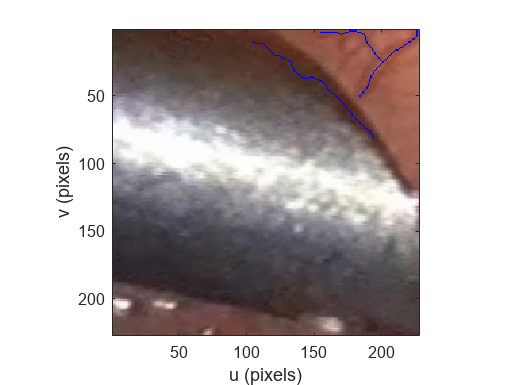

figure()
idisp(labeloverlay(img1, blood_vessel, 'Transparency', 0),'here')

 1:       0.516      0.4278      0.4652      0.3836 
 2:      0.3727      0.3542      0.3719      0.3443 


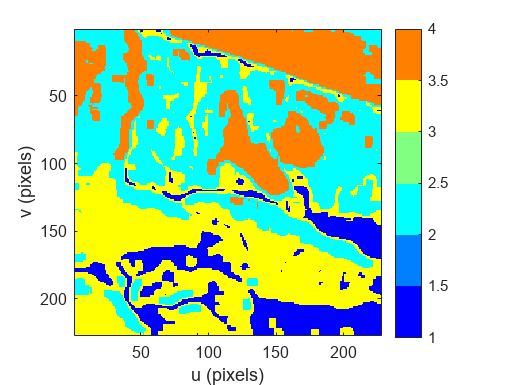

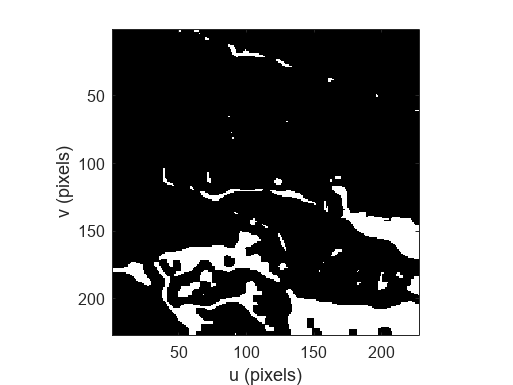


% ----------------------------------------------------------------------------------------------

path = fullfile("images_endovideo","random","frame_right22855.png");
img2 = iread(path, 'uint8');
gauss = 2;
max_luminosity = 200;
num_colors = 6;
cls_num = [0,1];
blood_vessel = blood_vessel_detection(img2, gauss, max_luminosity, numColors, cls_num);

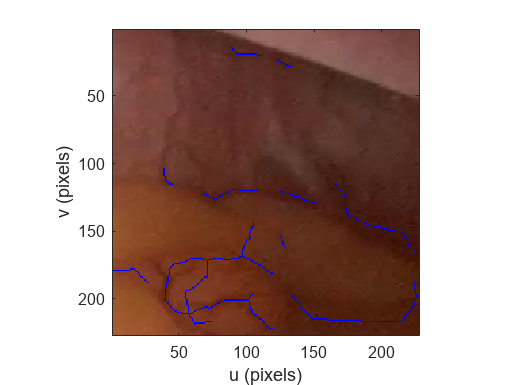

figure()
idisp(labeloverlay(img2, blood_vessel, 'Transparency', 0),'here')

## Function

function blood_vessel = blood_vessel_detection(img, gauss, max_luminosity, numColors, cls_num)
    % smoothing
    img_normalized = double(img) / double(max(img(:)));
    g = kgauss(gauss);
    padding = [5,5];
    padded_img = padarray(img_normalized, padding, 'replicate', 'both');
    %     smooth_img = locallapfilt(single(padded_img), 0.1, 2);
    %     smooth_img = smooth_img(padding(1)+1:size(img,1)+padding(1), padding(1)+1:size(img,2)+padding(1), :);
    imConv = iconvolve(padded_img, g, 'same');
    smooth_img = imConv(padding(1)+1:size(img,1)+padding(1), padding(1)+1:size(img,2)+padding(1), :);
    % edge enhancement
    smooth_img_padded = padarray(smooth_img, padding, 'replicate');
            % gauss = 4;
    G = kdgauss(gauss)./gauss^2;
    [Igu, Igv] = isobel(smooth_img_padded, G);
    Imag = sqrt(Igu.^2 + Igv.^2);
    Imag = Imag ./ max(Imag(:));
    Imag = Imag(padding(1)+1:size(img,1)+padding(1), padding(1)+1:size(img,2)+padding(1));
    edge_strength = 2.0; % Anpassen des Verstärkungsfaktors
    enhanced_img = im2double(smooth_img) + edge_strength * Imag;
    enhanced_img = max(min(enhanced_img, 1), 0);
    % contrasts
    shadow_lab = rgb2lab(enhanced_img);
            % max_luminosity = 70;
    L = shadow_lab(:,:,1)/max_luminosity;
    shadow_img = shadow_lab;
    shadow_img(:,:,1) = adapthisteq(L)*max_luminosity;
    shadow_img = lab2rgb(shadow_img);
    % erosion and dilation
    se = strel('disk', 3);
    img_eroded = imerode(shadow_img, se);
    img_dilated = imdilate(img_eroded, se);
    % segmentation
    rng('default');  % Setzen Sie den Zufallszahlengenerator auf den Standardwert
            % numColors = 4;
    [cls, ~] = colorkmeans(img_dilated, numColors);
    figure()
    idisp(cls, 'here','colormap', 'Jet(6)', 'bar')
    cls_i = (cls == cls_num(1) | cls == cls_num(2));
    figure()
    idisp(cls_i,'here', 'square')
    % Morphology
    se = kcircle(4);
    closed = imbinarize(iclose(cls_i, se));
    blood_vessel = bwskel(closed,'MinBranchLength',10);
end